## Validation and Verification on the NXP S32K396 MCU in Processor-in-the-Loop

In this exercise, you will learn how to prepare a Simulink model to be automatically Validated and Verified again in the test cases in Processor-in-the-Loop on the ARM Cortex-M7 Core of the NXP S32K396 MCU.

The model has been already prepared for the PIL execution. The exercise, provides a guide on the main settings that needs to be taken into account when running PIL on the NXP S32K3xx Hardware Board.

open_system('S32K39_FaultLogic_NXP_Codegen_Harness.slx')

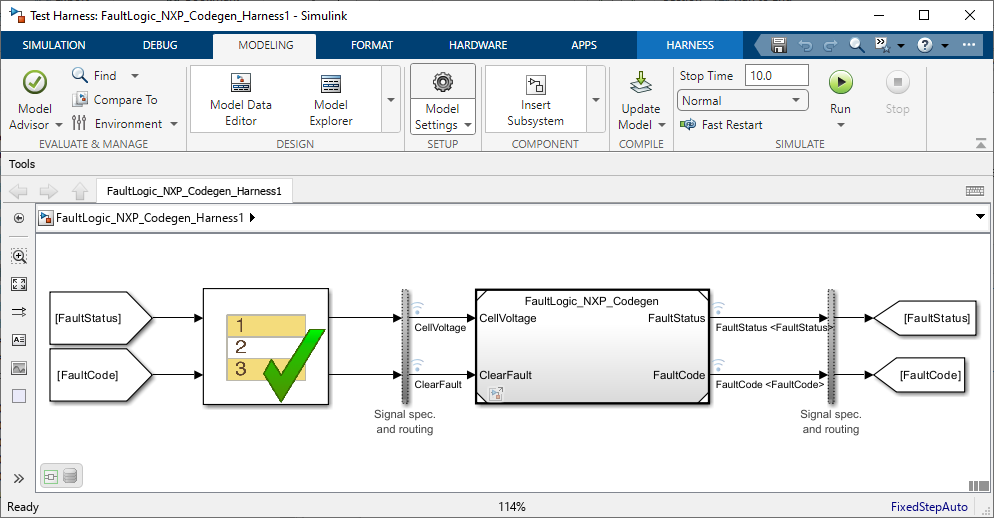

Open Model Settings

configSet = getActiveConfigSet('S32K39_FaultLogic_NXP_Codegen_Harness');
configSet.openDialog();

Check the Hardware Board to be set on NXP S32K3xx.

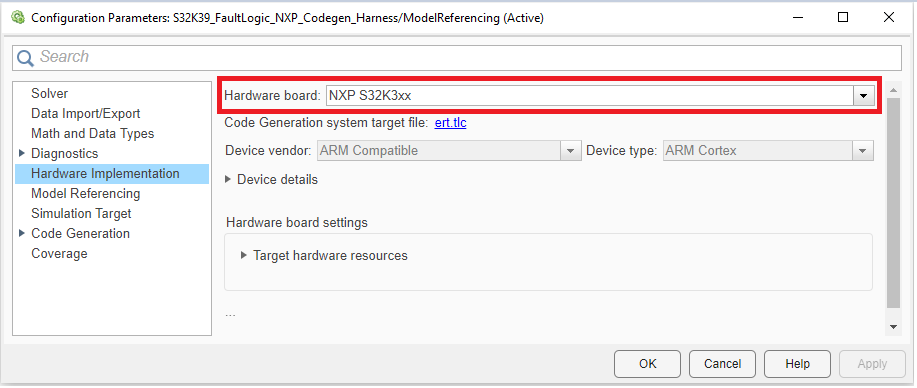

Expand the Target hardware resources.

Here are all the settings available for the NXP S32K3xx Hardware board. On the left-hand side, under Groups, there are located the main categories of the options available for the NXP Hardware Part (Hardware, Build Options, Timers, PIL, External mode, alongside all the settings for the configured components) and for this Simulink model targeting the NXP MCU (Referenced Configuration, Download, Tools Paths).

The **Hardware Part** under the **Hardware** Group selects the processor package. This is a critical setting for our Simulink model, because MBDT adjusts the external configuration tool project settings (clocking values, pins muxing, peripherals settings) for the selected Hardware Part. In our case, the **XS32K396-BGA-DC1 EVB **is populated with the **S32K396-Q289 MCU**, so this is the option we need to select.

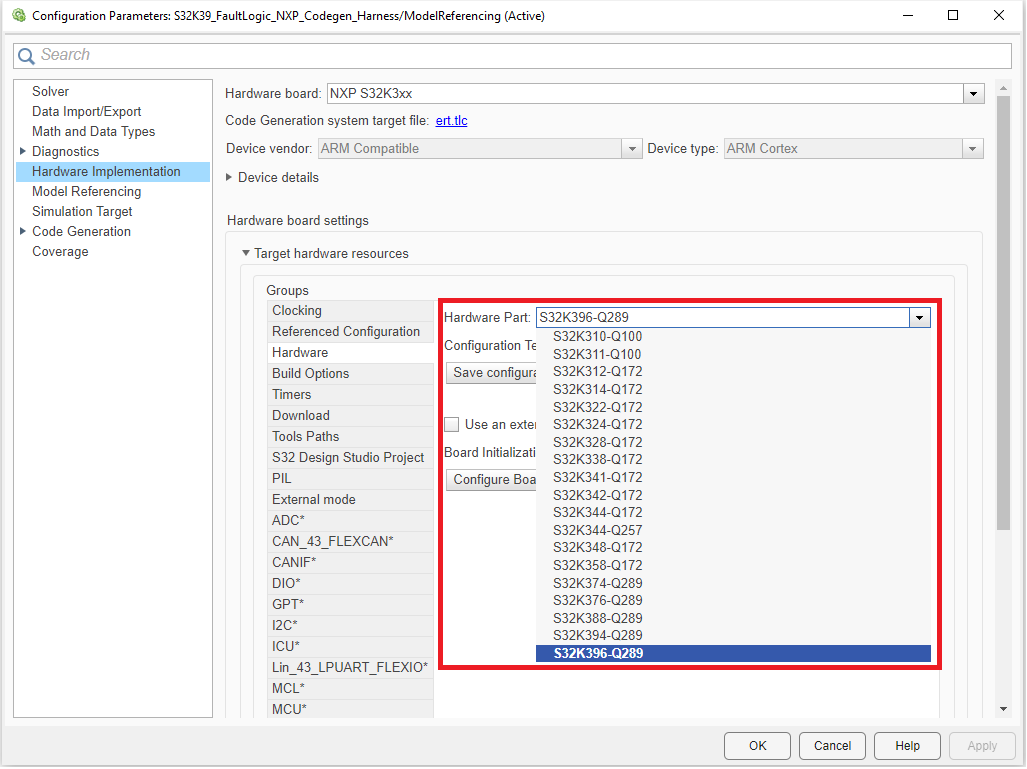

An Optional Setting is to select the **Configuration Tool** used to generate the initialization C code for the pins, clocks and peripherals of the MCU. The **S32 Configuration Tool** comes already embedded into MBDT, making it ready to be used once the MBDT is installed into **MATLAB**. MBDT is also compatible with the **EB Tresos Studio** but this tool needs to be installed separately and requires an additional license.

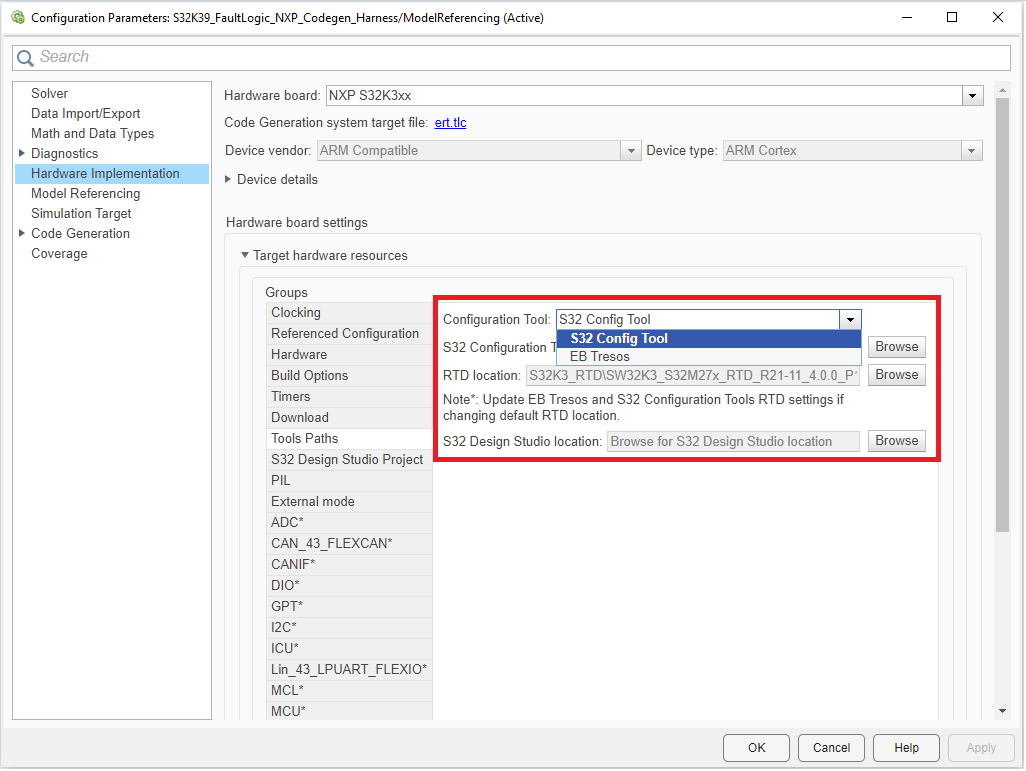

This leads us to the PIL Group settings. During the Processor-in-the-Loop validation, the board communicates constantly with the Simulink Harness, running on the PC via the Serial connection. The UART configuration on the board is automatically inserted by MBDT in the generated code, based on the selected options from the tab highlited below. 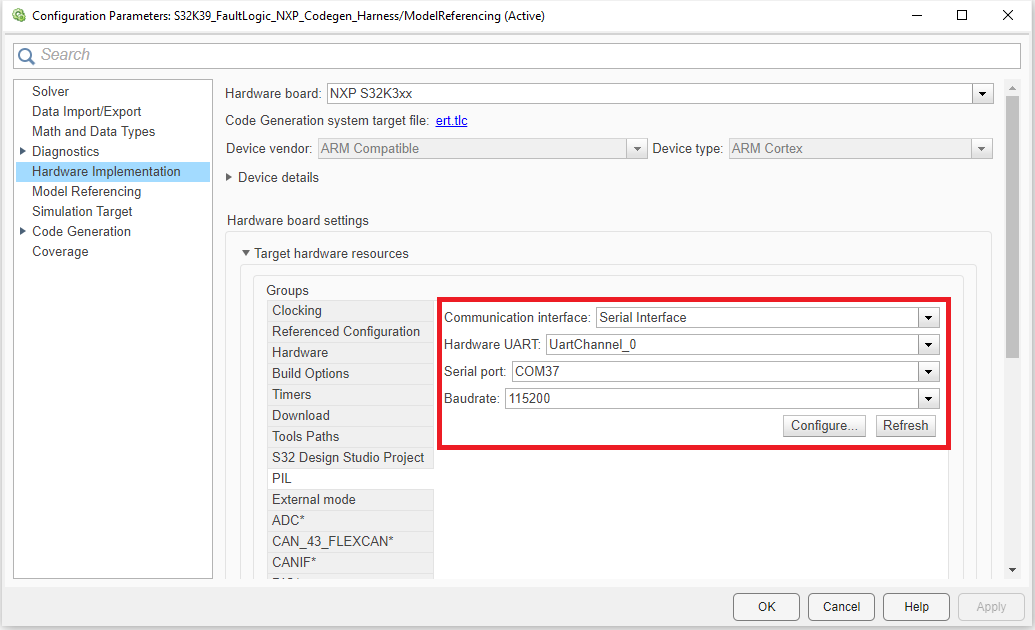

- **Communication interface** - selects the Serial Interface type used for the PIL communication.

- **Hardware UART** - selects the **Uart channel** configured via the **external configuration tool**. In our case, the selected **UartChannel_0**, uses the **LPUART_0** instance of the **LPUART** peripheral from the S32K396 MCU. This configuration comes default to match the S32K3 EVBs, but if PIL is executed on a custom hardware board, the Uart Channels can be configured by pressing the **Configure...** button in the Configuration parameters.         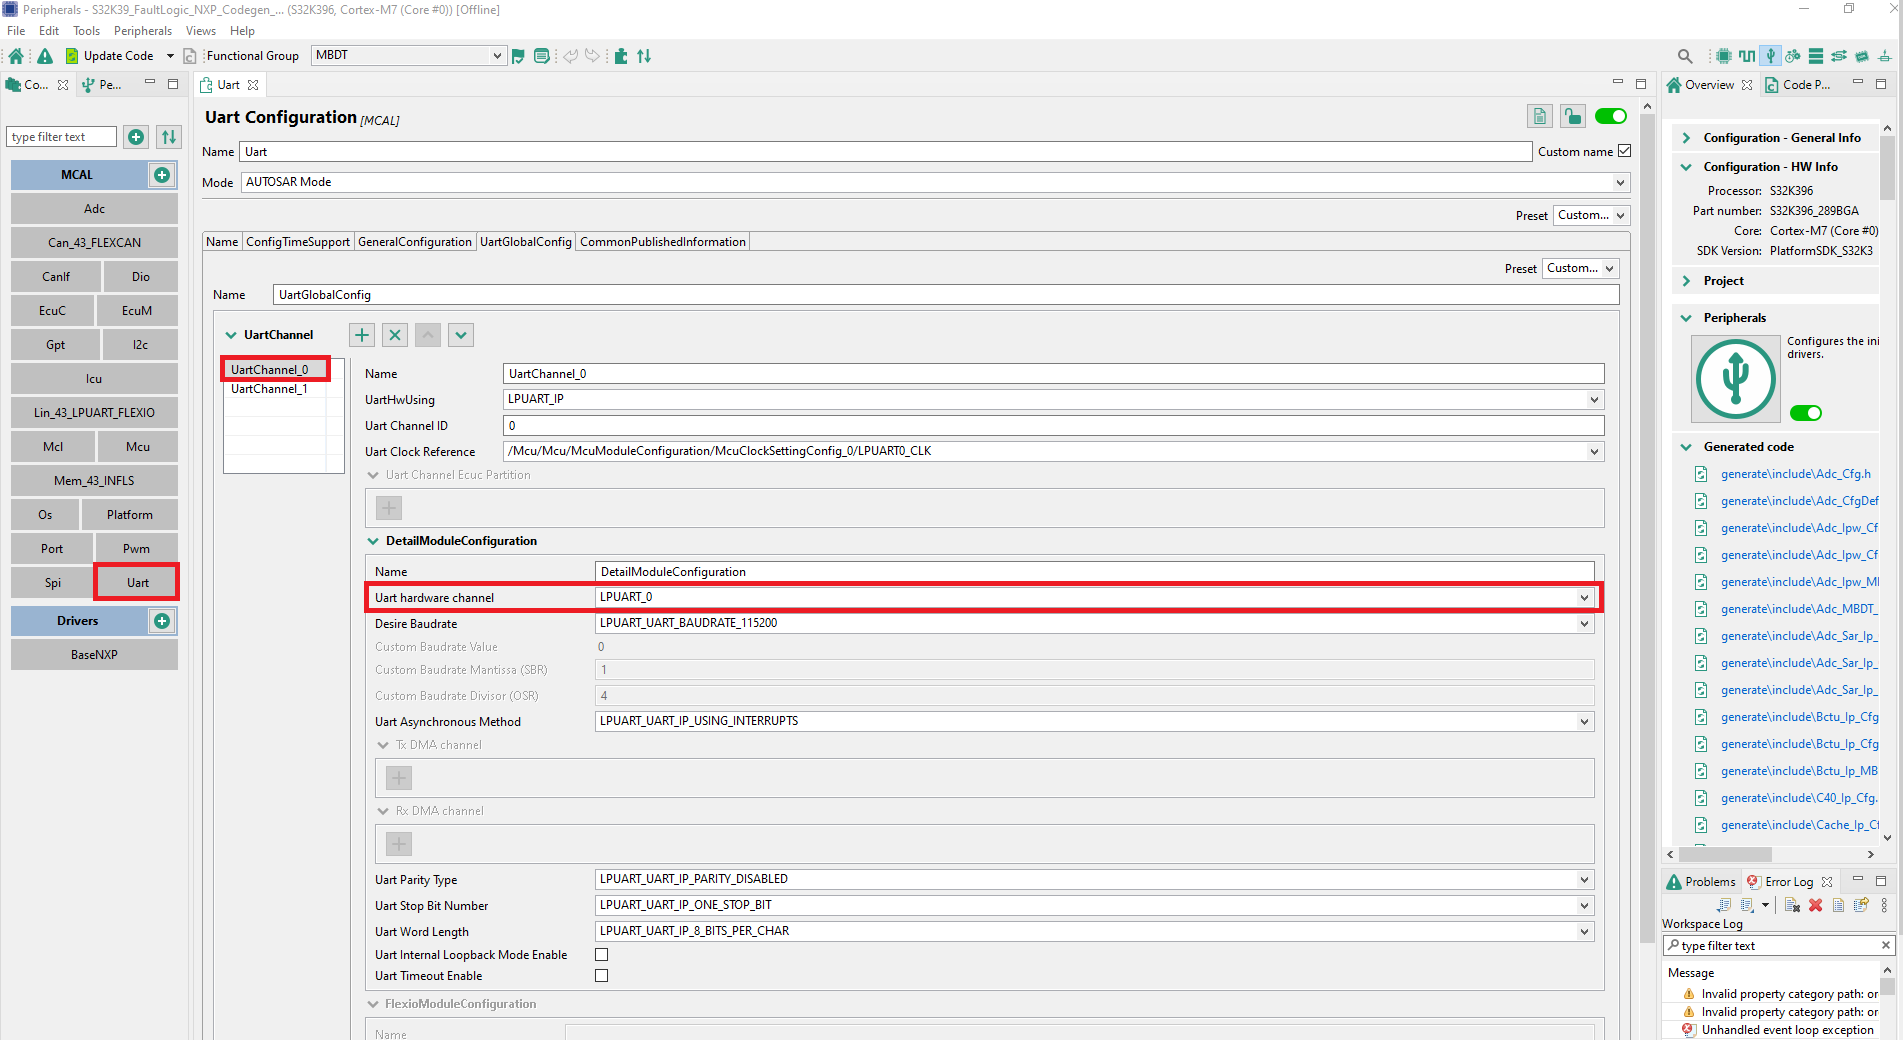

- **Serial port** -  selects the PC serial COM port assiged to the S32K396-BGA-DC1 EVB. The dropdown options are automatically populated with all the available ports when the **Refresh** button is pressed. A way to easily detect the associated COM port to the board is to disconnect the board from the PC, execute the command below, then connect the S32K396 EVB board back to the PC and execute the command again. The new port available is the one associated with the S32K396 EVB. This is a key setting for a successful PIL execution.

serialportlist("available")

- **Baudrate** - represents the Serial data transfer speed. By default this is configured to a 115200. 

Code execution time profiling could be enabled from the **Code Generation** -> **Verification** settings group.

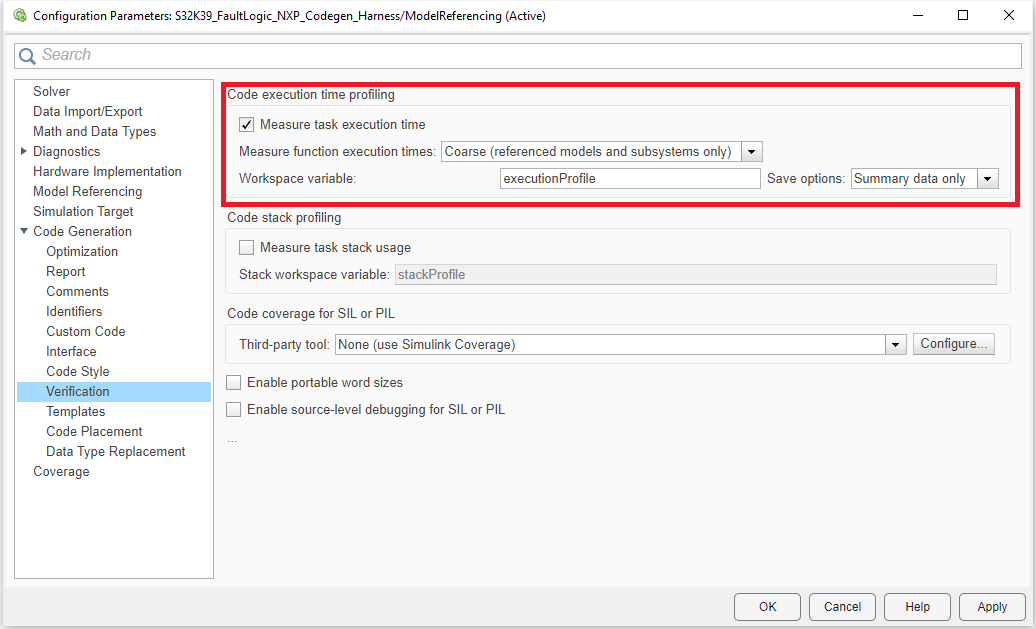

**Note! Simulink Harness model needs to have the same settings configured with the Test Model. The configuration can be easily copied via the Model Explorer.**

Run the command below to open the Model Explorer.

sfexplr

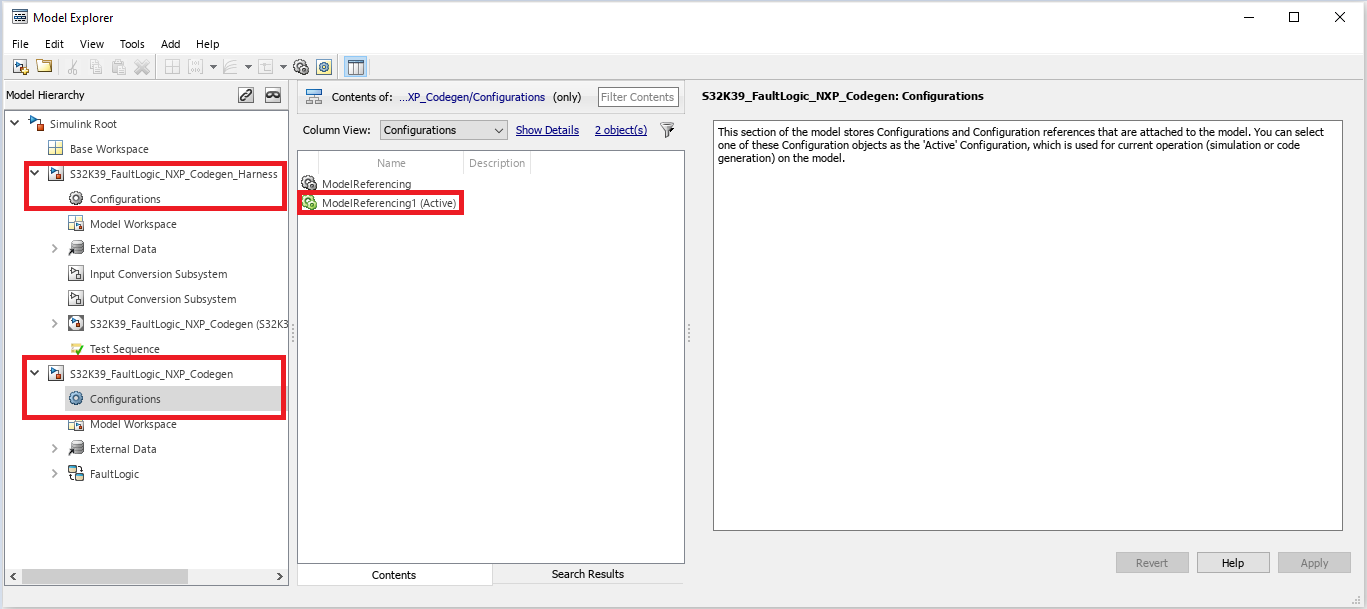

### Running PIL

Go to SIL/PIL Manager and select the options for the SIL/PIL execution.

1.  **MODE** tab provides 3 options:

- **Automated Verification** - Performs model simulation on the computer, then runs SIL/PIL on the target MCU. Then performs an output data accuracy comparison between the results in MIL vs SIL/PIL.

- **Simulation Only **- Performs ONLY model simulation on the computer.

- **SIL/PIL Simulation Only** - Performs ONLY model simuation in SIL/PIL mode.

2. **PREPARE** provides the selection for the SIL/PIL for the System Under Test.

3. **Run Verification** button starts the execution of the MIL/SIL/PIL test.

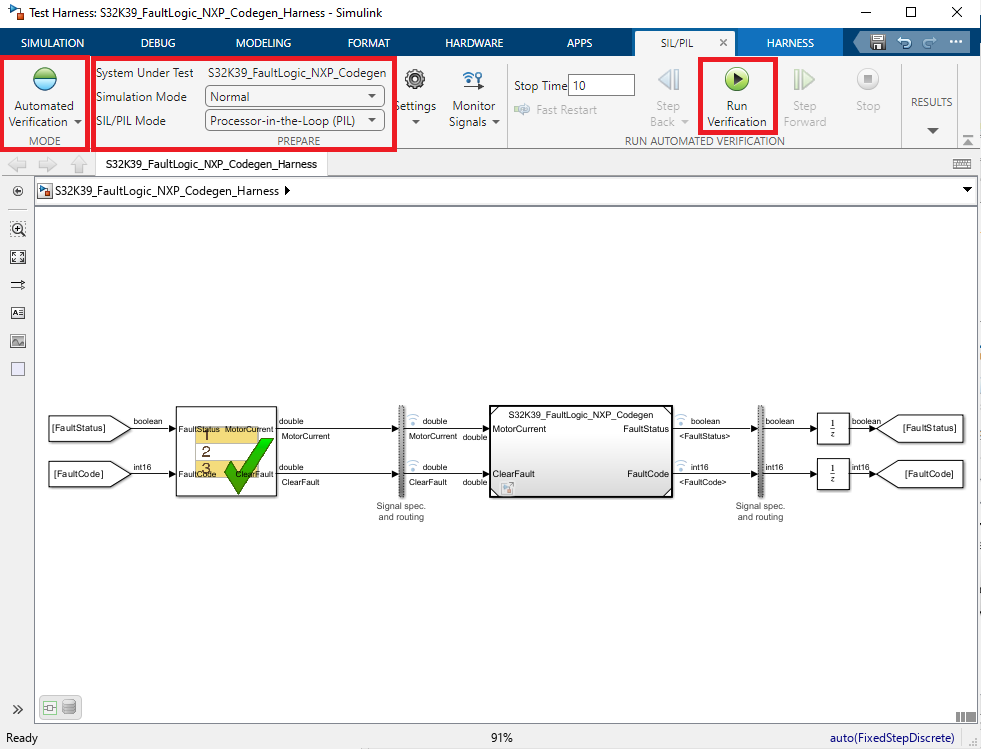

Once the tests have been executed, we could analyze the results via Simulink Data Inspector, as seen below.

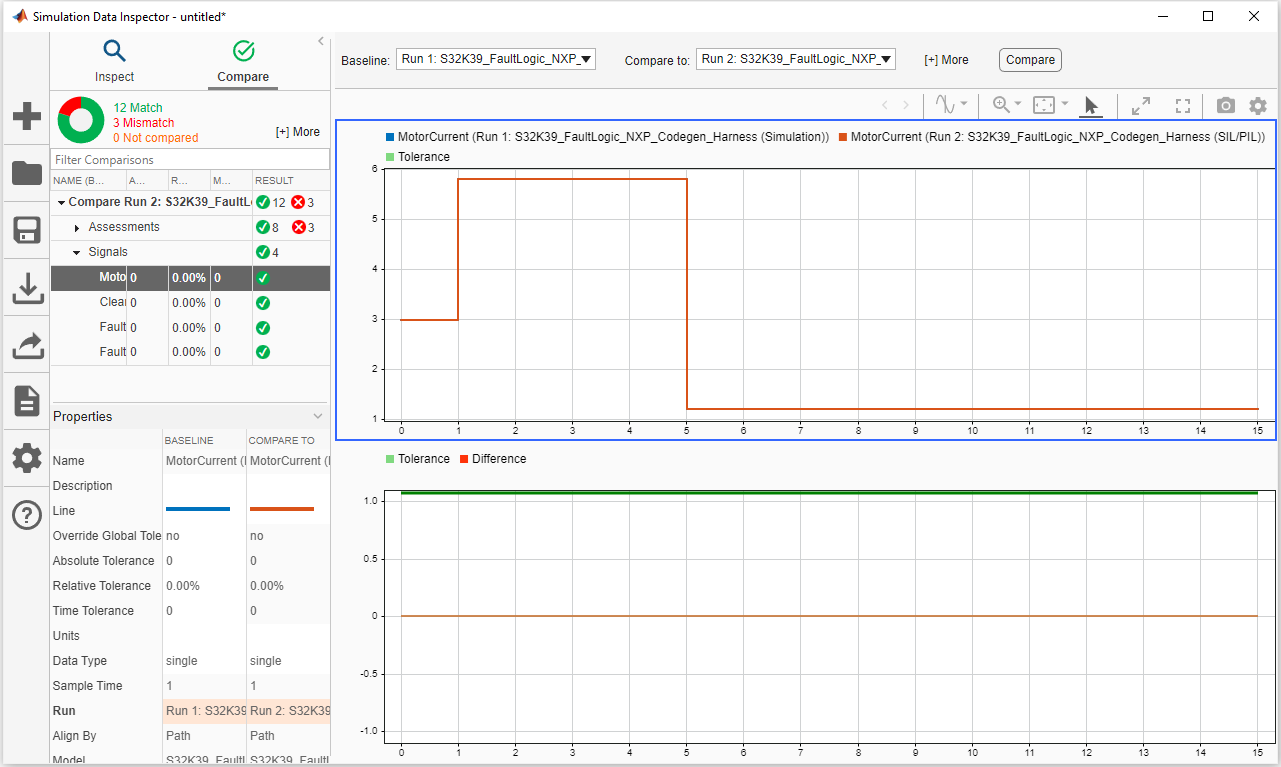

The generated code for the FaultLogic could be analyzed in the Code section of the Simulink model.

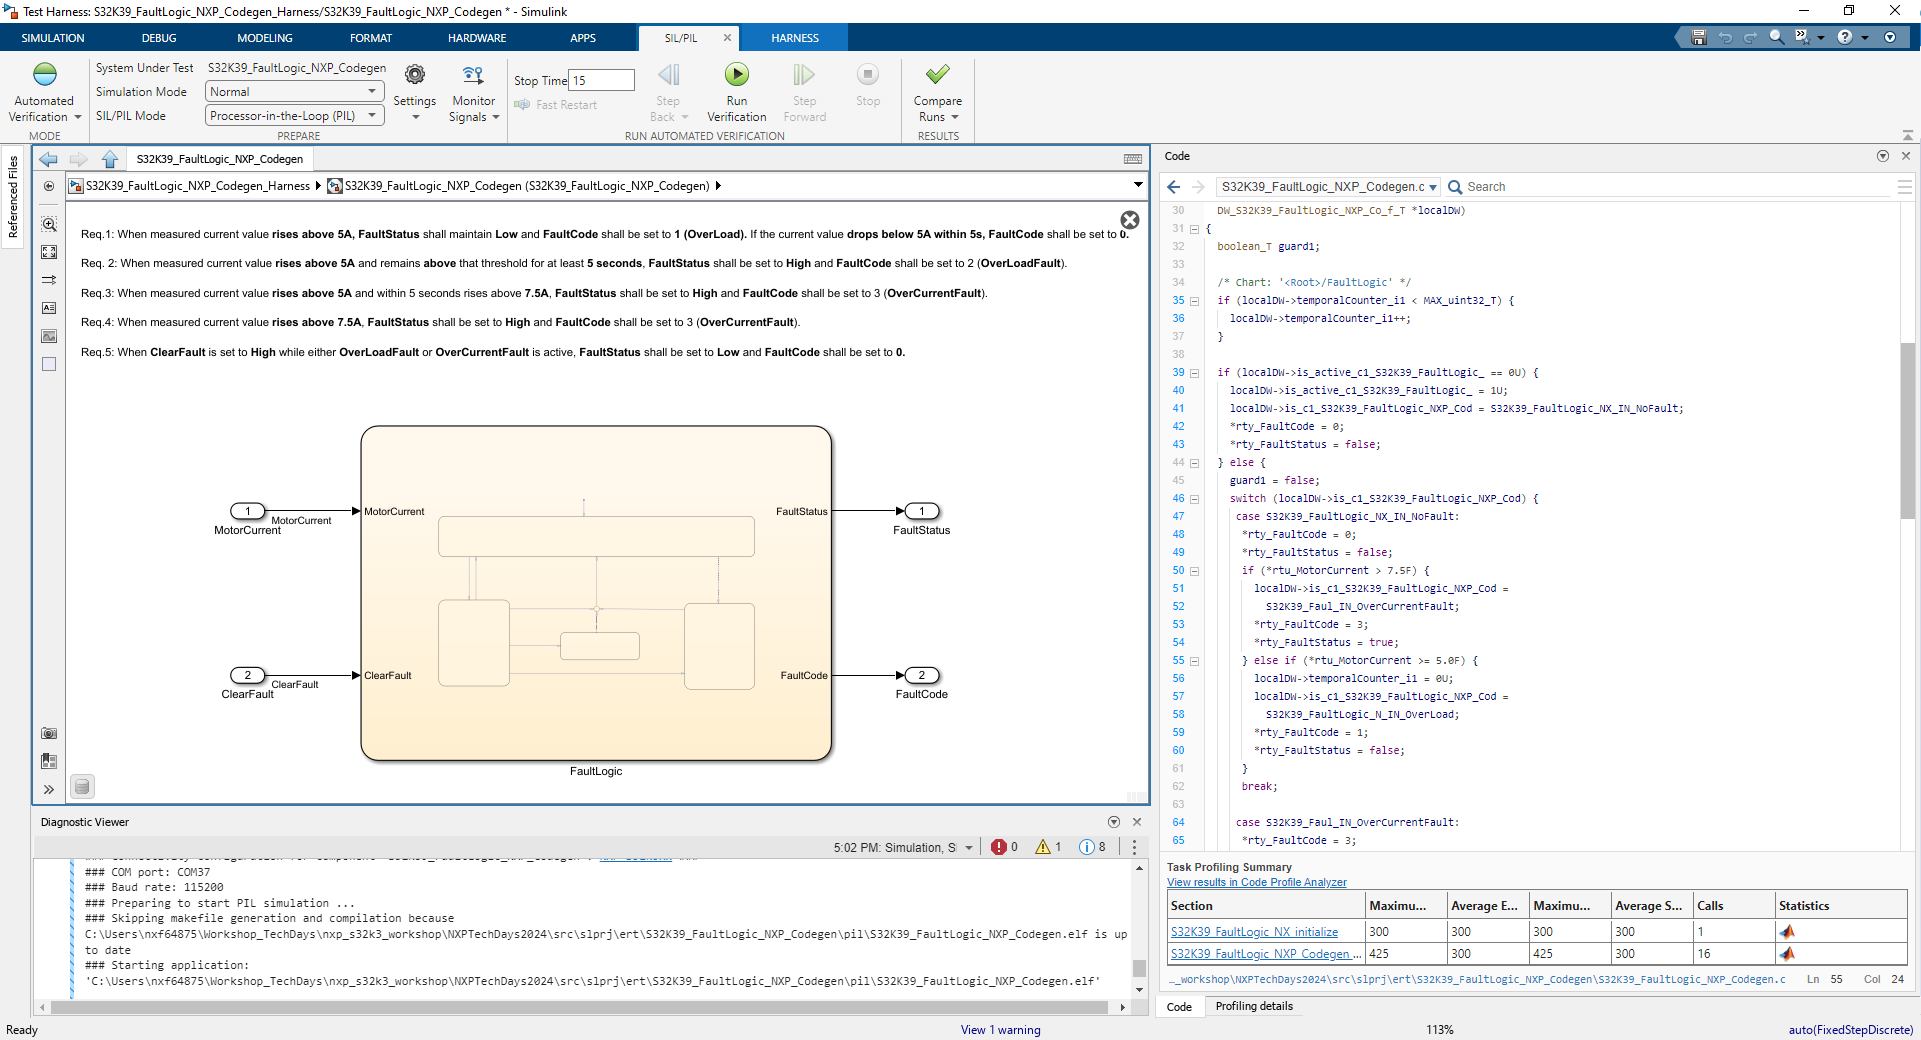

Coge Execution Profiling Report provides information regarding the execution performance on the NXP target.